# Script di stima della RUL di motori di aerei

clc, close all, clear all

%%%%%%%%%%%%%%%%%%%%%%%%%%% INSERIRE PATH SPECIFICO PER UTENTE CORRENTE %%%%%%%%%%%%%%%%%%%%%%%%%%%
%path = 'C:/Users/sam/Desktop/PHM2021_Data_Challenge_Exam_Project/cluster_set/';
path = 'C:/Users/mat98/source/repos/PHM2021_Data_Challenge_Exam_Project/cluster_set/';
fileList = {'N-CMAPSS_cluster_0_cycle.csv', 'N-CMAPSS_cluster_1_cycle.csv', 'N-CMAPSS_cluster_2_cycle.csv'};
numeroClusters = length(fileList)

numeroClusters = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Costruzione Health Indicator


for num_cluster = 1:numeroClusters
    filename = string(append(path,fileList(num_cluster)));
    
    T = readtable(filename);

    % aggiunta istanti di tempo associati ad ogni misurazione dei sensori
    unita_totali = unique(T.unit);
    TT = timetable();
    for i=1:length(unita_totali)
        indici_righe = find(T.unit == unita_totali(i));
        T_filter = T(indici_righe, :);
        TT2 = array2timetable(T_filter, 'RowTimes', seconds(1:size(T_filter)));
        TT = vertcat(TT, TT2);
    end

    T = addvars(T, TT.Time, 'NewVariableNames', 'Time');

    
    % imposta il valore della percentuale
    perc_training = 0.7;
    
    % calcola la dimensione delle due parti
    n1 = floor(length(unita_totali) * perc_training);
    n2 = length(unita_totali) - n1;
    
    rng(42);
    
    indici = randperm(length(unita_totali));
        
    unita_training = unita_totali(indici(1:n1));
        
    unita_test = unita_totali(indici(n1+1:end));
    
    T_training = T(ismember(T.unit, unita_training), :);
    T_test = T(ismember(T.unit, unita_test), :);



    varNames = string(T.Properties.VariableNames);
    
    timeVariable = varNames(22);
    conditionVariables = varNames(17:20);
    dataVariables = varNames(1:14);

    clusterTrainNormal = cell(num_cluster,1);
    clusterValidNormal = cell(num_cluster,1);
    centerstats = struct('Mean', table(), 'SD', table());

    % Normalizzazione training
    for v = dataVariables
            centerstats(num_cluster).Mean.(char(v)) = mean(T_training.(char(v)));
            centerstats(num_cluster).SD.(char(v)) = std(T_training.(char(v)));
    end

    for motore=1:length(unita_training)
        tablesensNorm = table();
        indici_righe = find(T.unit == unita_training(motore));
        T_filter = T(indici_righe, :);
        for v = dataVariables
                tablesensNorm.Time = T_filter.Time;
                sensorToNorm = T_filter.(char(v));
                sensNorm = (sensorToNorm - centerstats(num_cluster).Mean.(char(v)))./centerstats(num_cluster).SD.(char(v));
                tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
                tablesensNorm.(char(z)) = T_filter.(char(v));
        end
        clusterTrainNormal{num_cluster,1}{motore,1} = tablesensNorm;
        
    end

    % Normalizzazione test
    for v = dataVariables
            centerstats(num_cluster).Mean.(char(v)) = mean(T_test.(char(v)));
            centerstats(num_cluster).SD.(char(v)) = std(T_test.(char(v)));
    end
    
    for motore=1:length(unita_test)
        tablesensNorm = table();
        indici_righe = find(T.unit == unita_test(motore));
        T_filter = T(indici_righe, :);
        for v = dataVariables
                tablesensNorm.Time = T_filter.Time;
                sensorToNorm = T_filter.(char(v));
                sensNorm = (sensorToNorm - centerstats(num_cluster).Mean.(char(v)))./centerstats(num_cluster).SD.(char(v));
                tablesensNorm.(char(v)) = sensNorm;
        end
        for z = conditionVariables
                tablesensNorm.(char(z)) = T_filter.(char(v));
        end
        clusterValidNormal{num_cluster,1}{motore,1} = tablesensNorm;
        
    end

    %% trendability analysis on each sensor
    numSensors = length(dataVariables);
    signalSlope = zeros(numSensors, 1);
    warn = warning('off');
    for ct = 1:numSensors
        tmp = cellfun(@(tbl) tbl(:, cellstr(dataVariables(ct))), clusterTrainNormal{num_cluster,1}, 'UniformOutput', false);
        %mdl = linearDegradationModel(); % create model
        mdl = exponentialDegradationModel();
        fit(mdl, tmp); % train mode
        signalSlope(ct) = mdl.Theta;    
    end
    warning(warn);

    % prendiamo gli 8 sensori che hanno valori di Theta maggiori, ovvero
    % gli 8 che hanno più pendenza, che sono più rappresentativi
    [~, idx] = sort(abs(signalSlope), 'descend');
    sensorTrended = sort(idx(1:8));

     5
     6
     7
    12



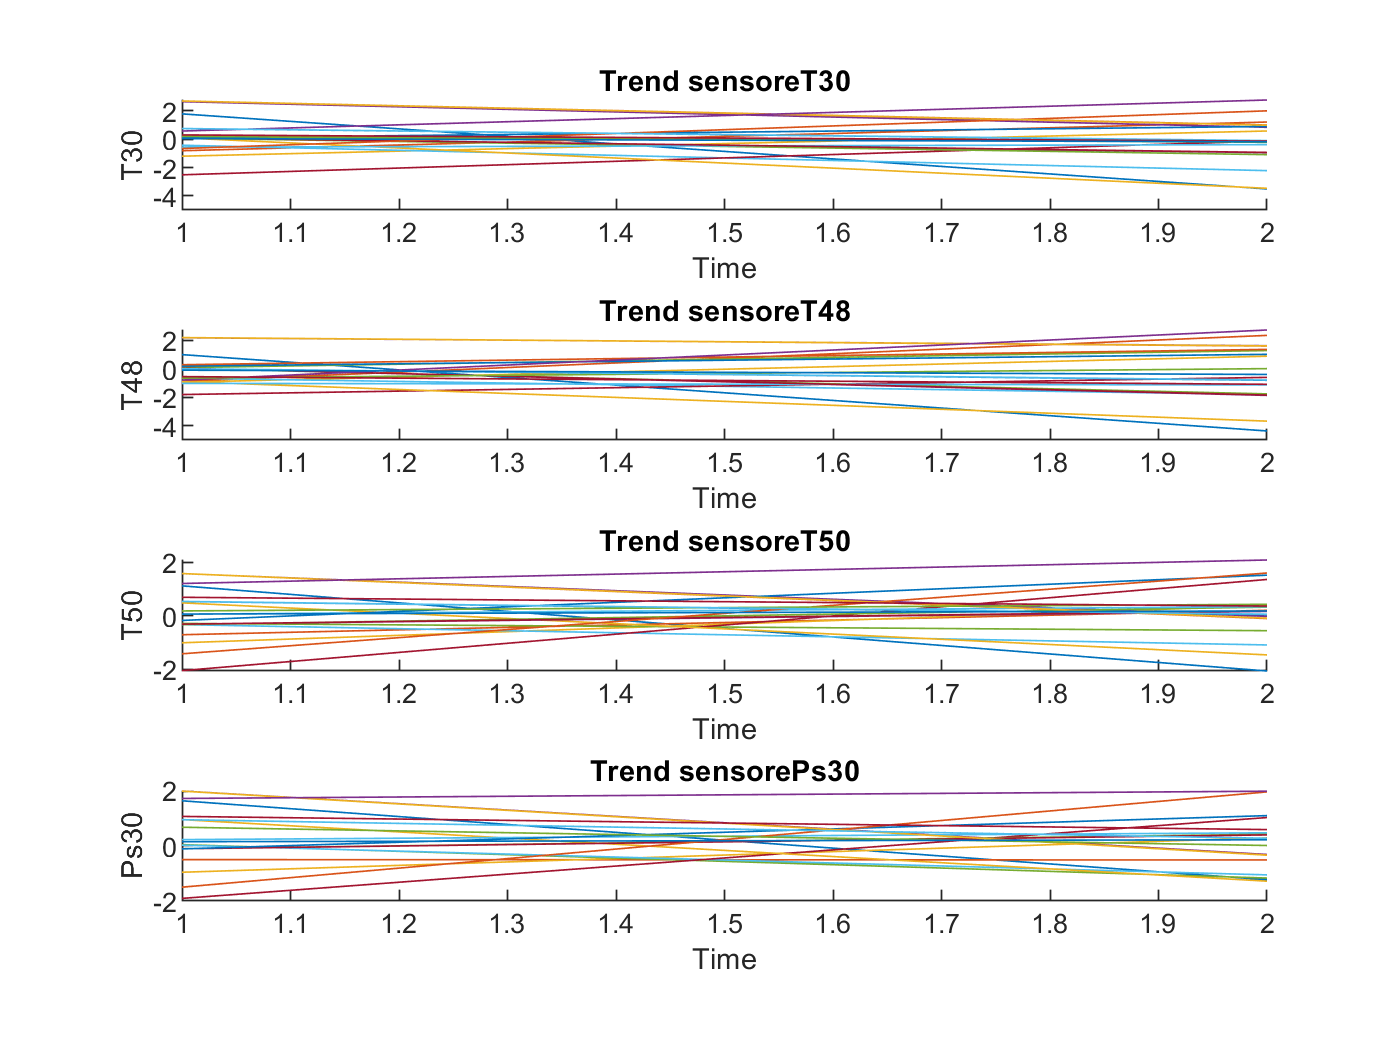

     6
     7
     9
    10



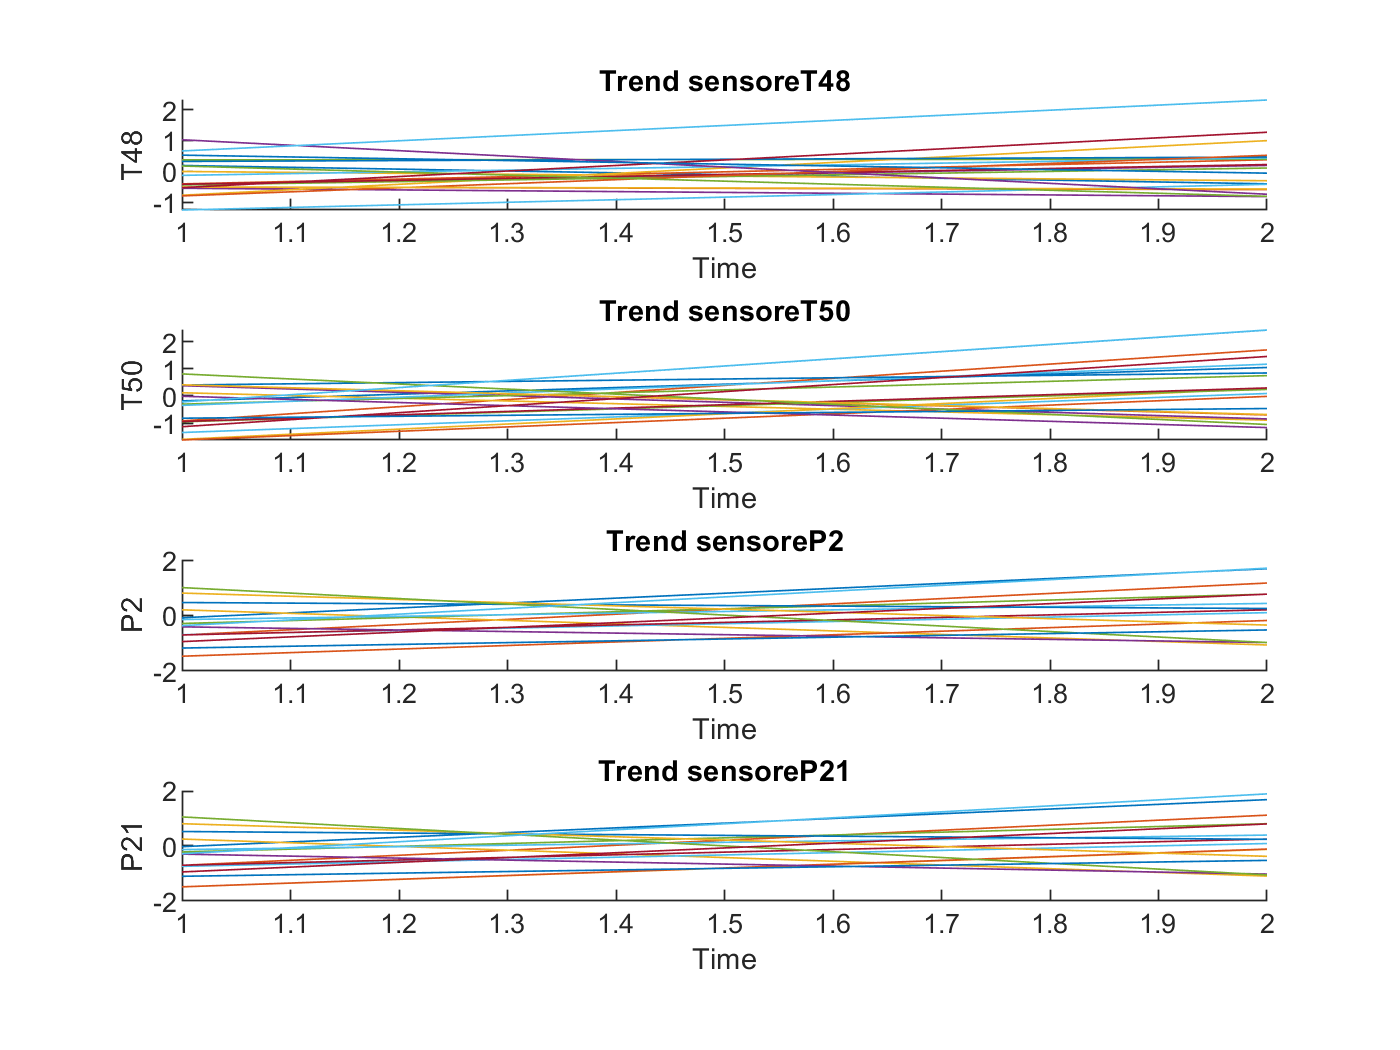

     8
     9
    10
    11



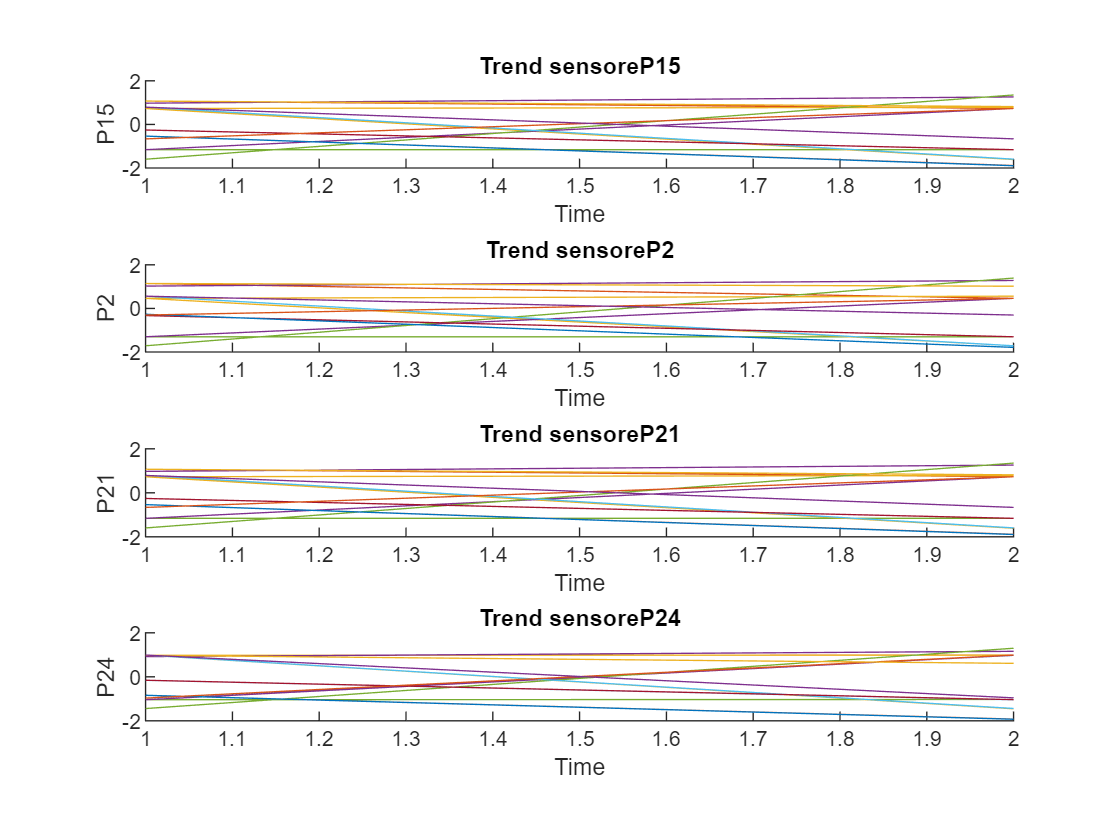

    nsample = 50;
    helperPlotEnsemble(clusterTrainNormal{num_cluster,1}, sensorTrended, dataVariables, nsample)

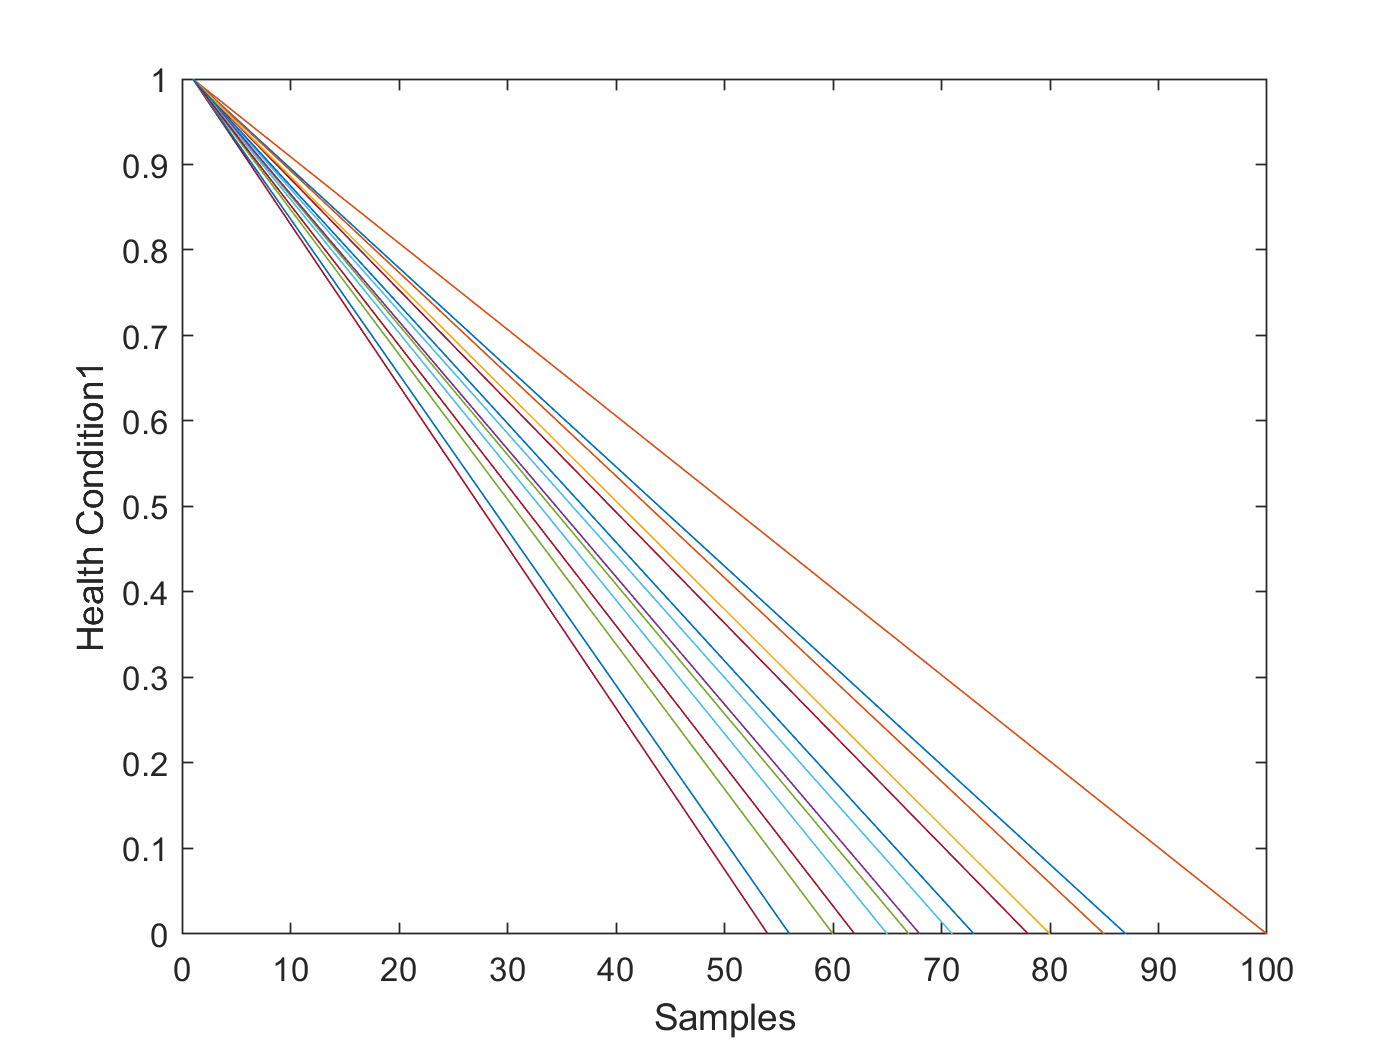

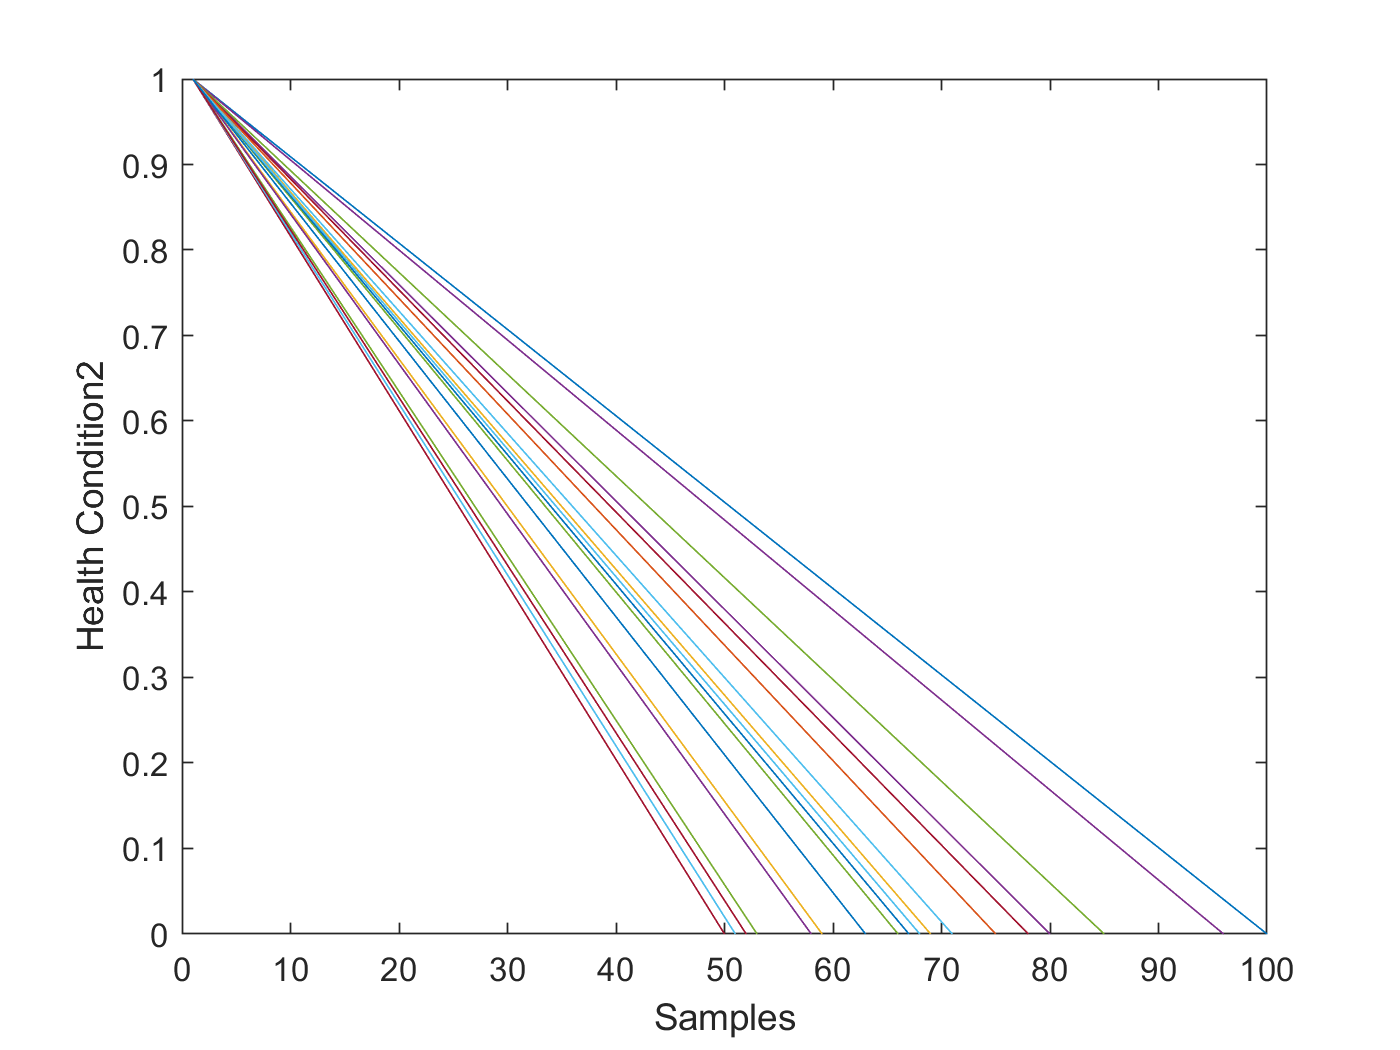

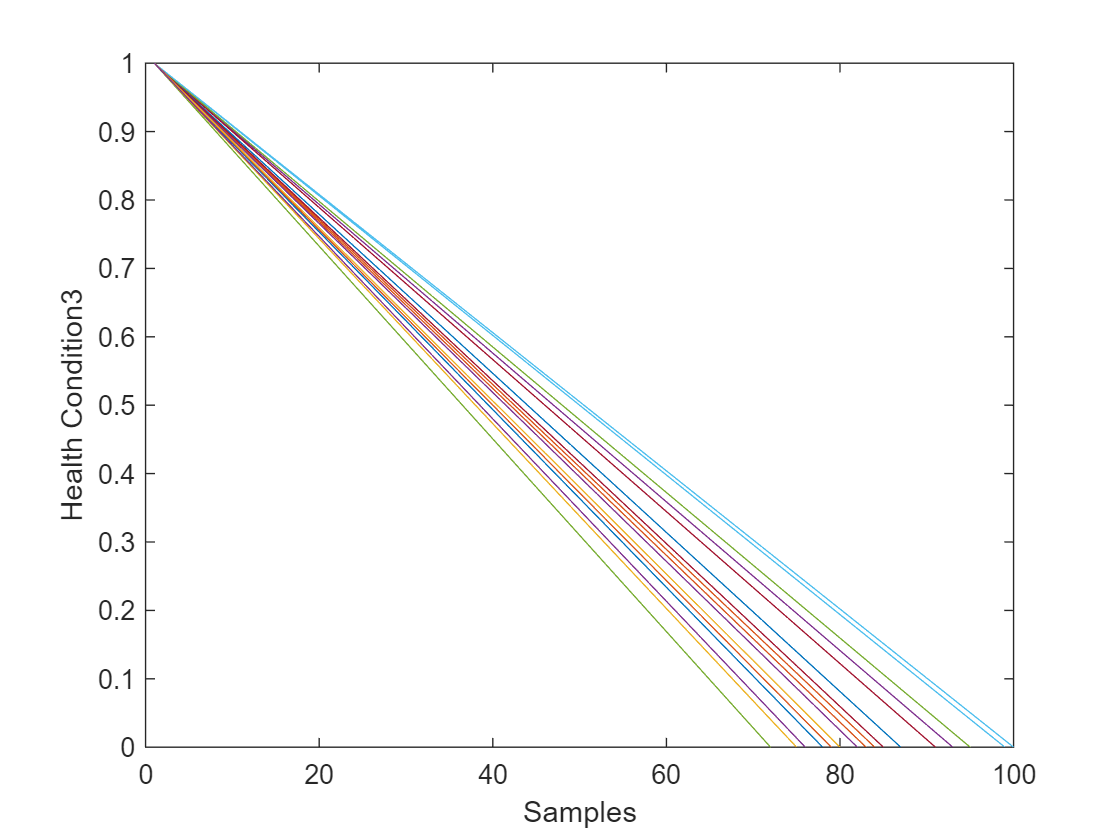

    figure
        for motore = 1:numel(clusterTrainNormal{num_cluster,1})
            data = clusterTrainNormal{num_cluster,1}{motore};
            rul = max(data.Time)-data.Time;
            data.health_condition = rul / max(rul);
            clusterTrainNormal{num_cluster,1}{motore} = data;
        
            plot(clusterTrainNormal{num_cluster,1}{motore}.health_condition)
            % title('trainData');
            ylabel("Health Condition"+string(num_cluster));
            xlabel("Samples");
            hold on
        end

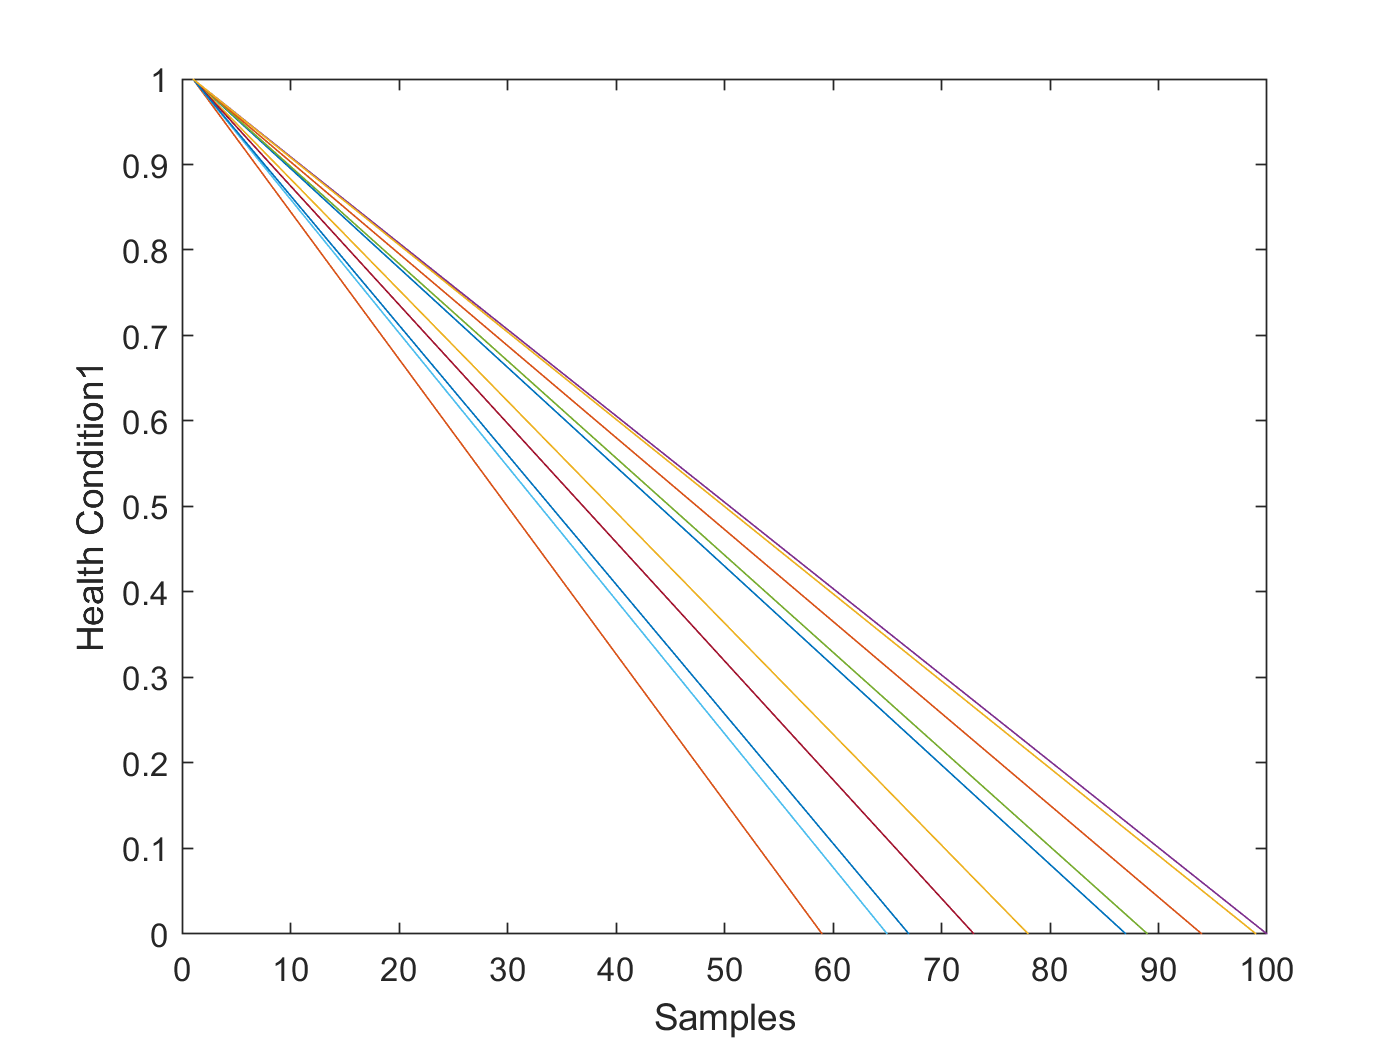

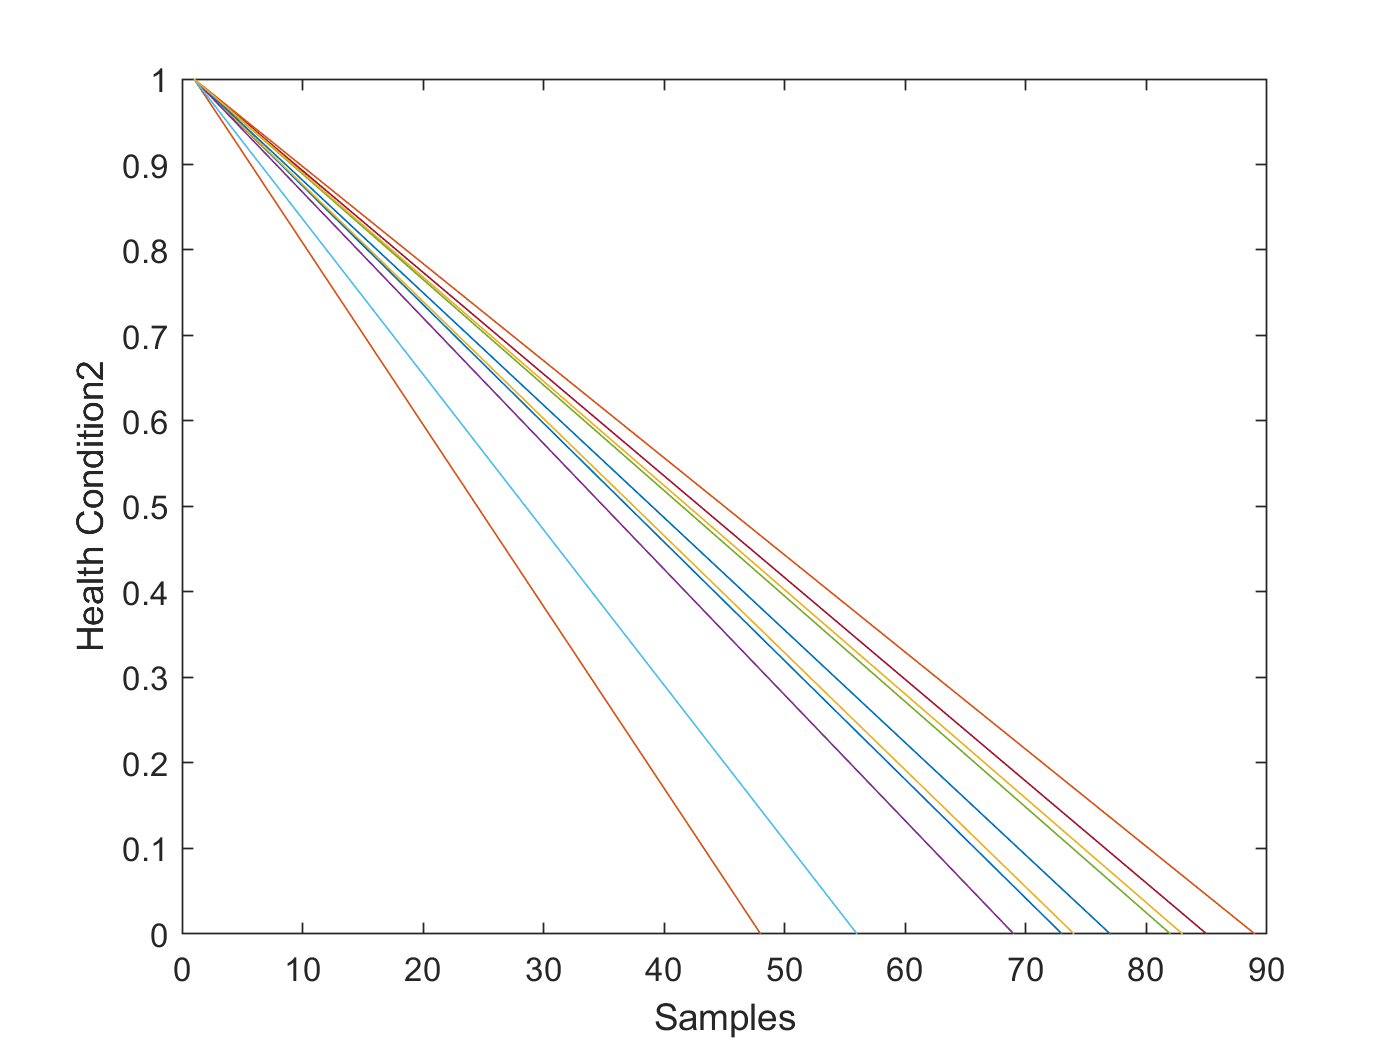

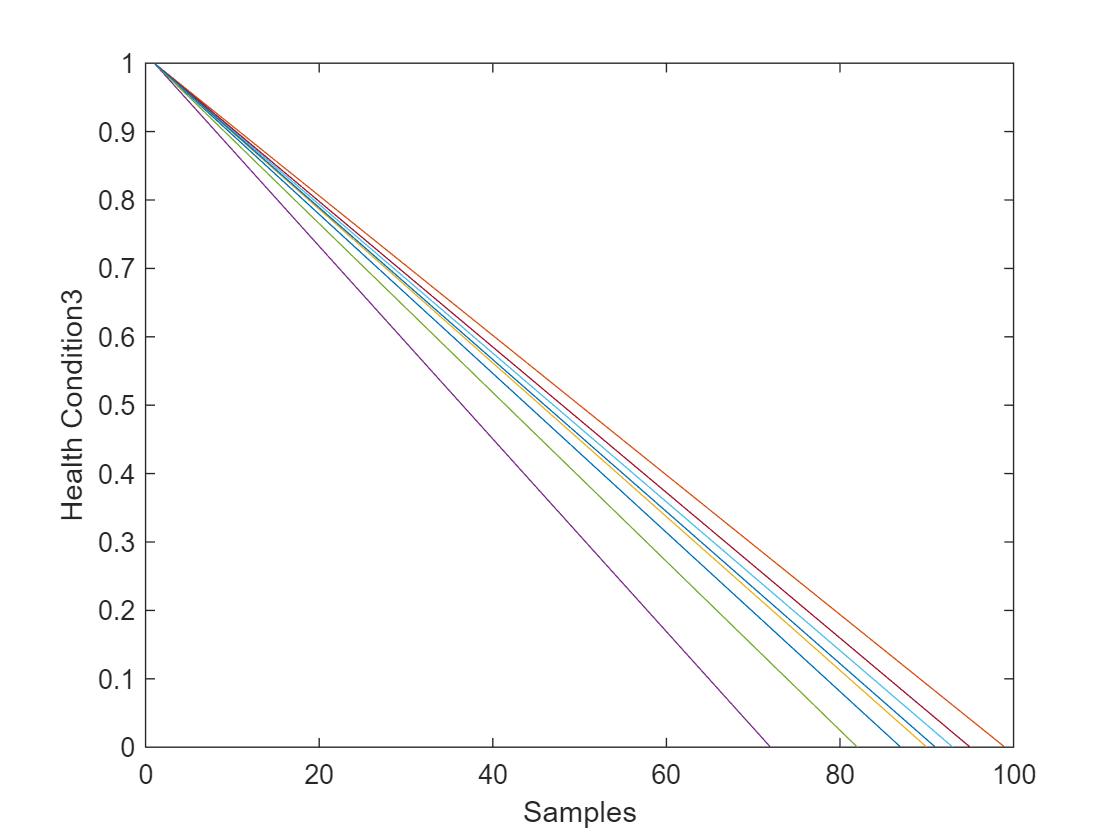

        
        figure
        for motore = 1:numel(clusterValidNormal{num_cluster,1})
            data = clusterValidNormal{num_cluster,1}{motore};
            rul = max(data.Time)-data.Time;
            data.health_condition = rul / max(rul);
            clusterValidNormal{num_cluster,1}{motore} = data;
        
            plot(clusterValidNormal{num_cluster,1}{motore}.health_condition)
            % title('validationData');
            ylabel("Health Condition"+string(num_cluster));
            xlabel("Samples");
            hold on
        end

     %% fitting linear model for unified health indicator
        trainDataNormalizedUnwrap = vertcat(clusterTrainNormal{num_cluster,1}{:});
        
        sensorToFuse = dataVariables(sensorTrended);
        X = trainDataNormalizedUnwrap{:, cellstr(sensorToFuse)};
        y = trainDataNormalizedUnwrap.health_condition;
        regModel = fitlm(X,y);

        
        bias = regModel.Coefficients.Estimate(1)

bias = 0.5000

bias = 0.5000

bias = 0.5000

        weights = regModel.Coefficients.Estimate(2:end)

weights =    -0.2453
   -0.1158
    0.0145
    0.0369
   -0.0750
   -9.3371
    9.5651
   -0.0719


weights =    -0.2847
    0.0078
   -0.1416
   -0.4367
   -6.6884
    7.6429
   -6.1944
    5.8740


weights =    -0.2036
   -0.3115
   -1.8472
    1.0939
         0
    0.1698
    1.9769
   -0.9730


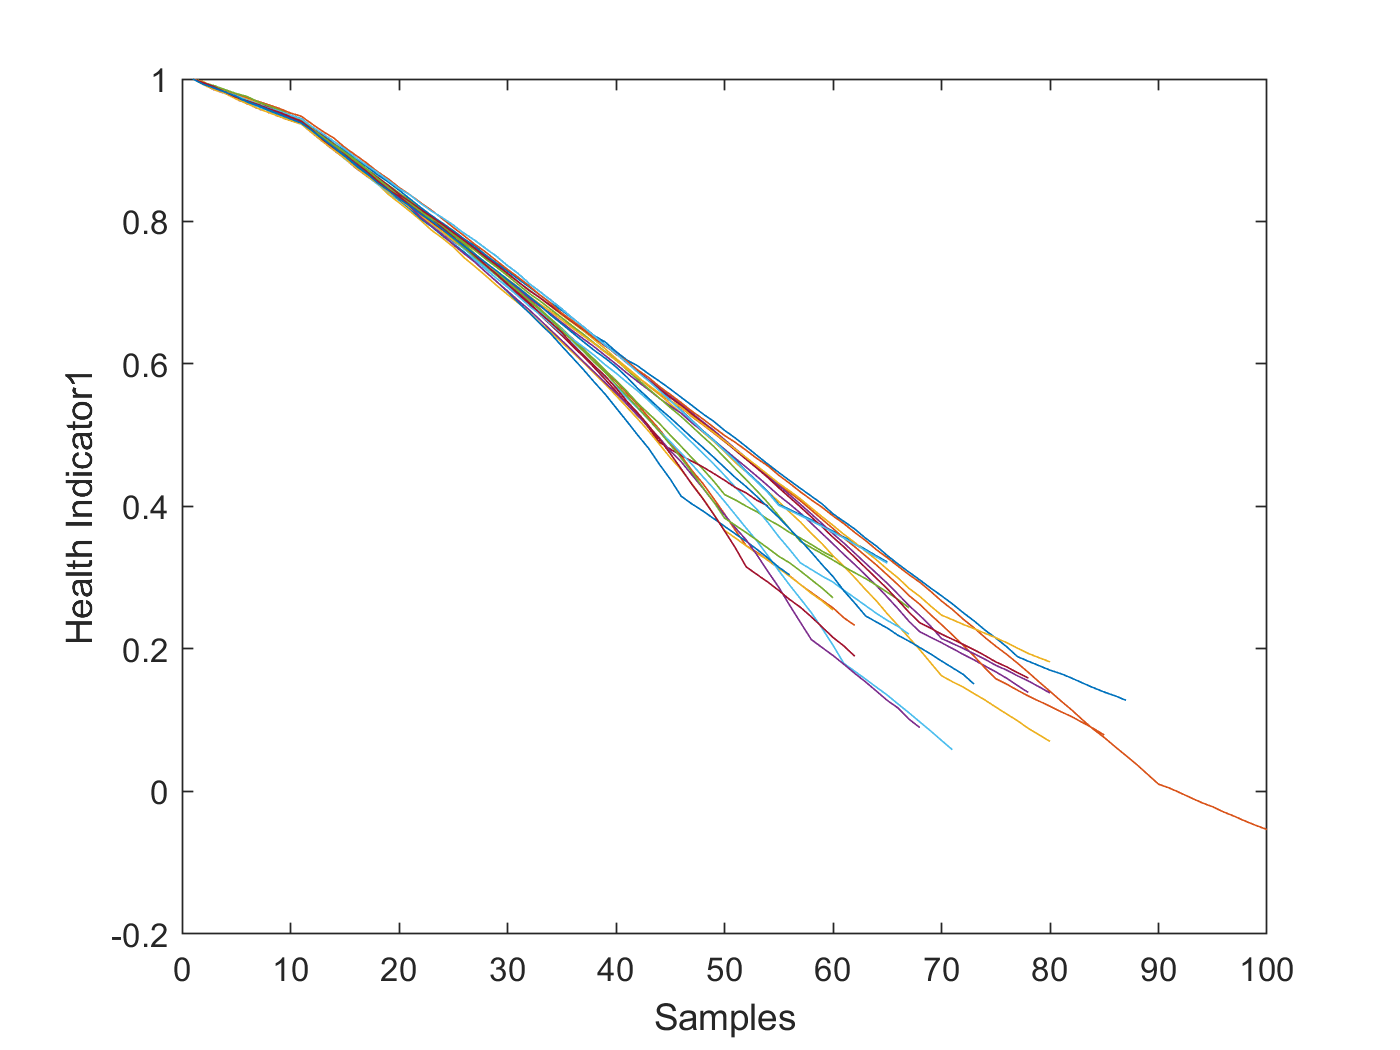

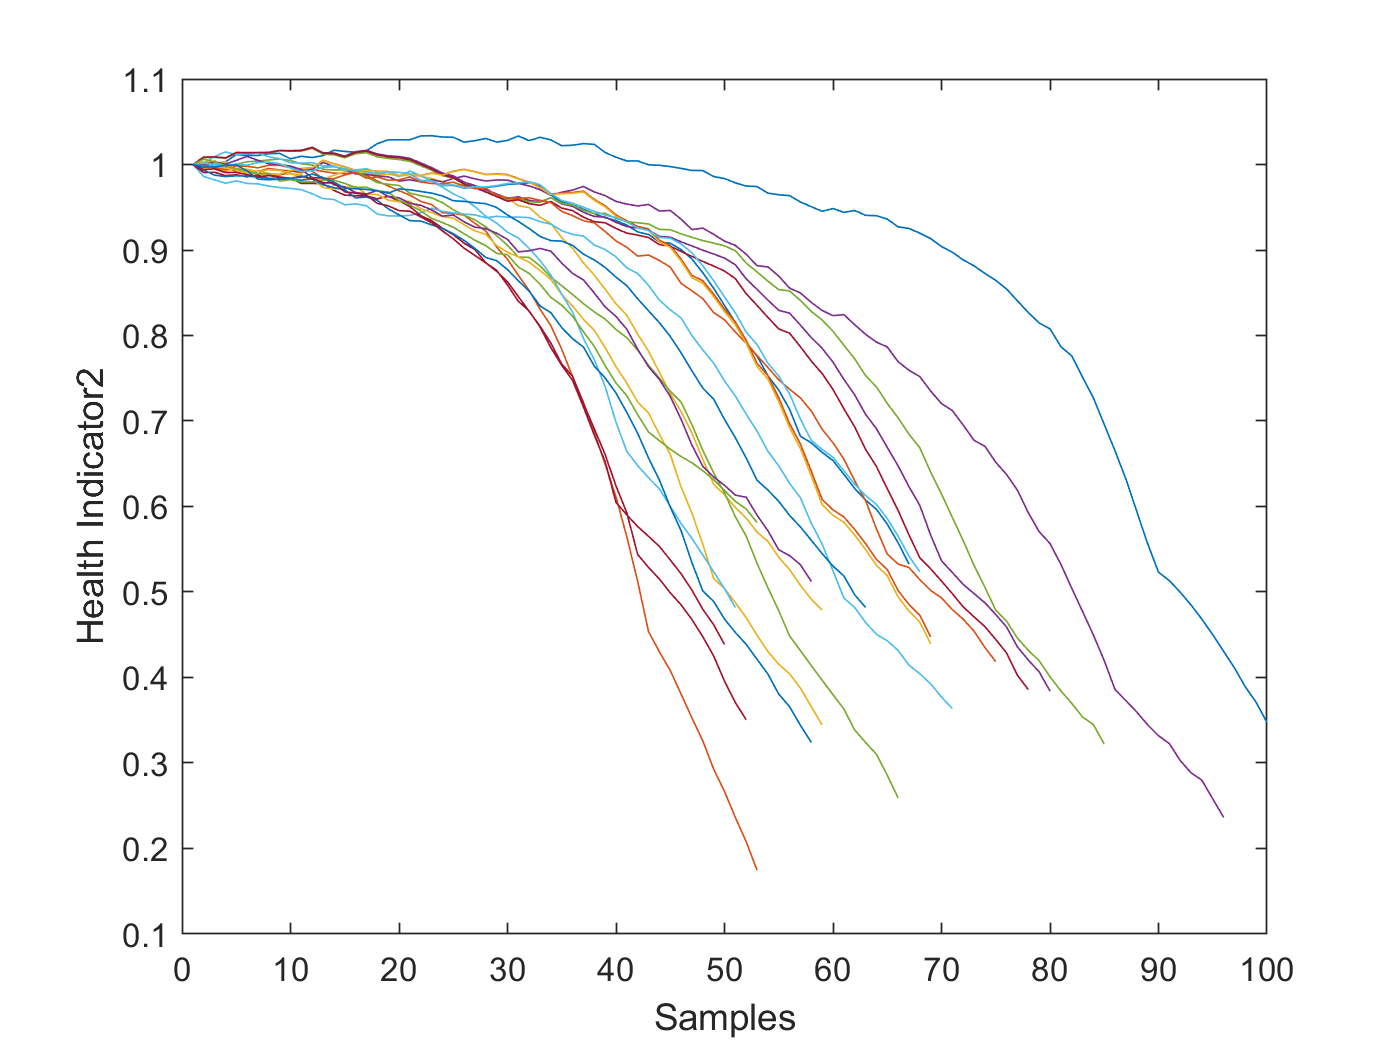

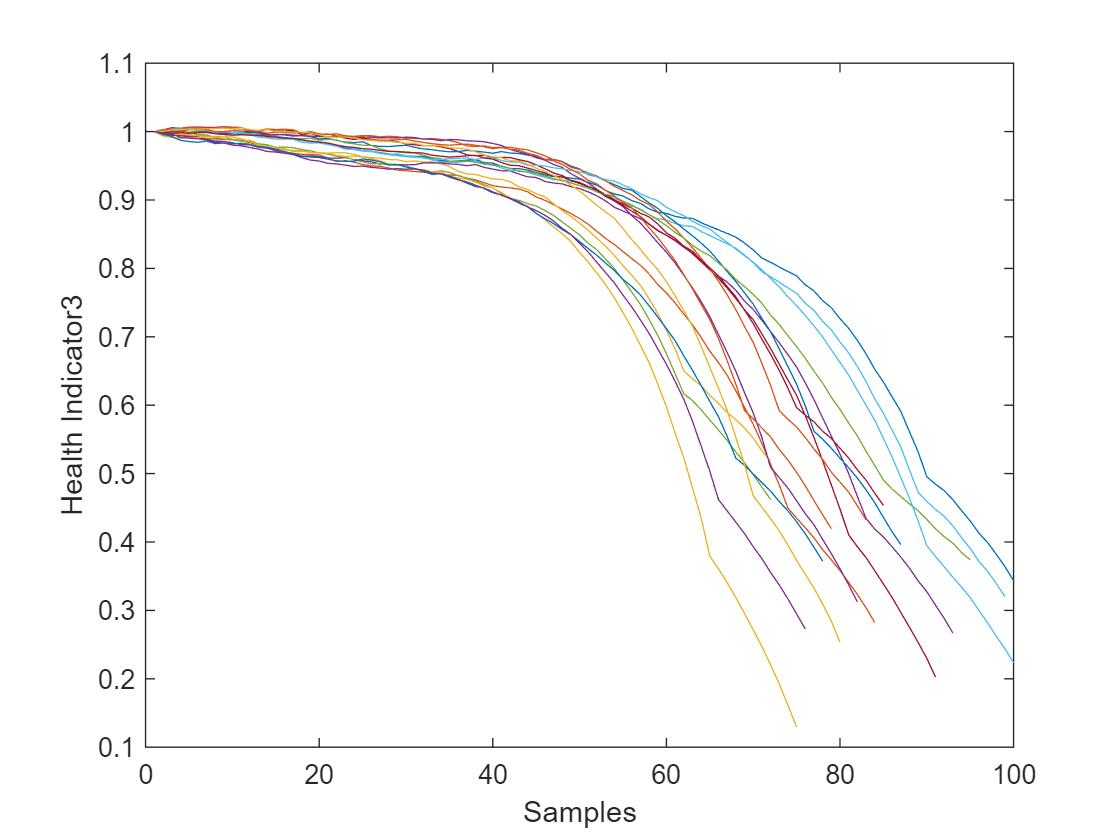

        
        
        %% unified health condition
        trainDataFused{num_cluster,1} = cellfun( @(data) degradationSensorFusion(data, sensorToFuse, weights), clusterTrainNormal{num_cluster,1}, ...
            'UniformOutput', false);
        %if num_cluster == 2
        %    trainDataFused{num_cluster,1}=trainDataFused{num_cluster,1}([1:2,4:end]);
        %end 
     
        validationDataFused{num_cluster,1} = cellfun(@(data) degradationSensorFusion(data, sensorToFuse, weights), ...
            clusterValidNormal{num_cluster,1}, 'UniformOutput', false);
        
        figure
        for k = 1:length(trainDataFused{num_cluster,1})
            plot(trainDataFused{num_cluster,1}{k})
            % title('trainDataFused')
            xlabel('Samples')
            ylabel('Health Indicator'+string(num_cluster))
            % title('Training Data')
            hold on
        end

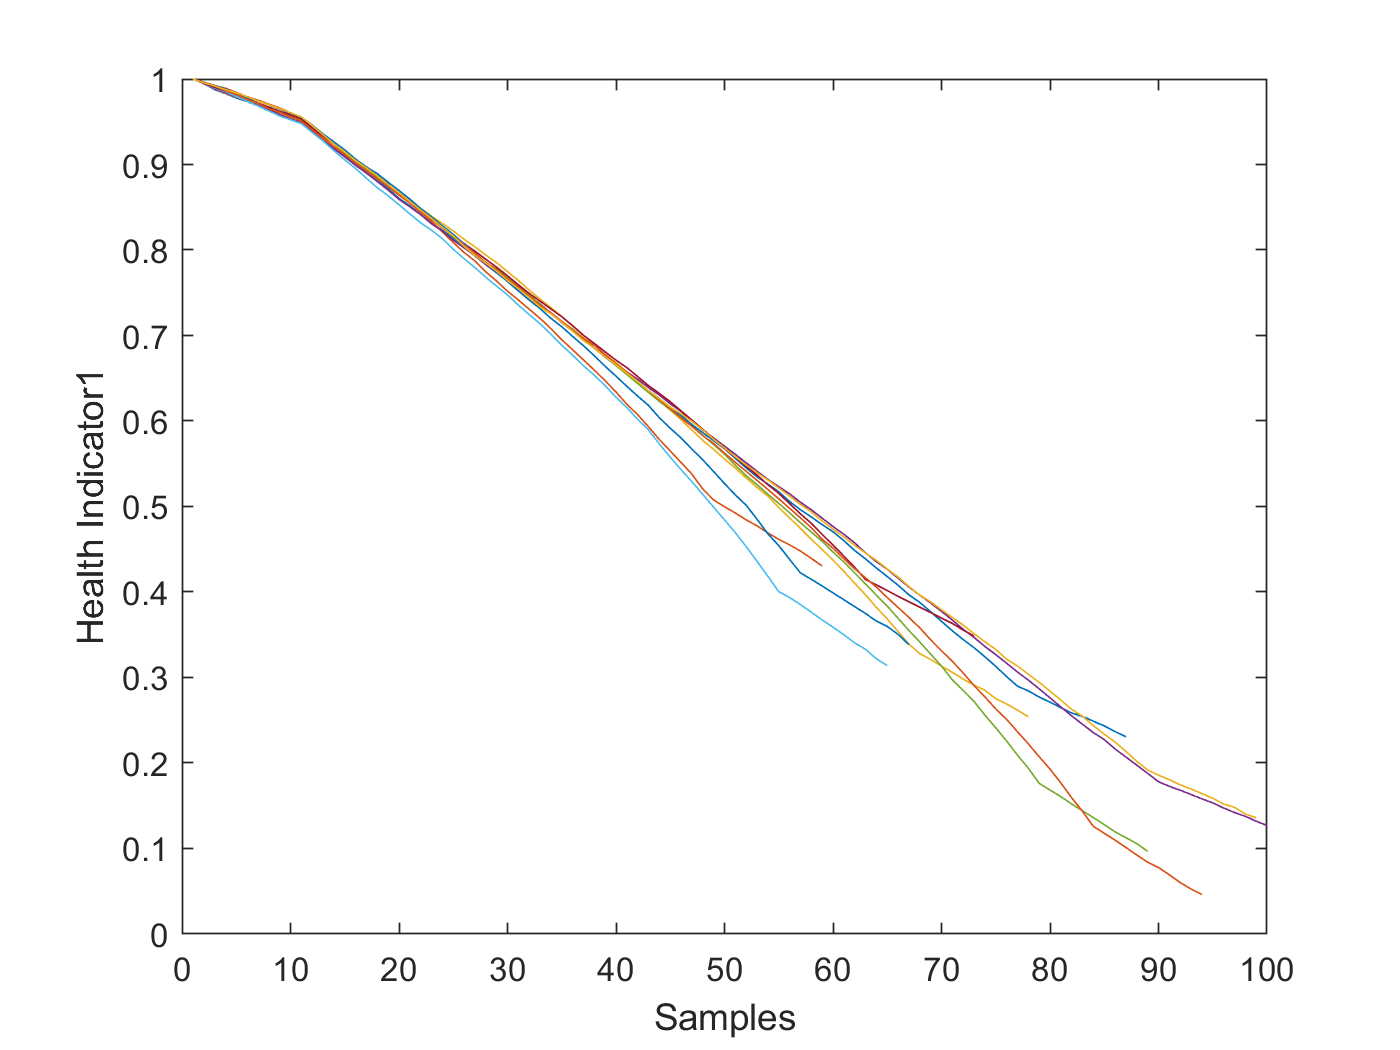

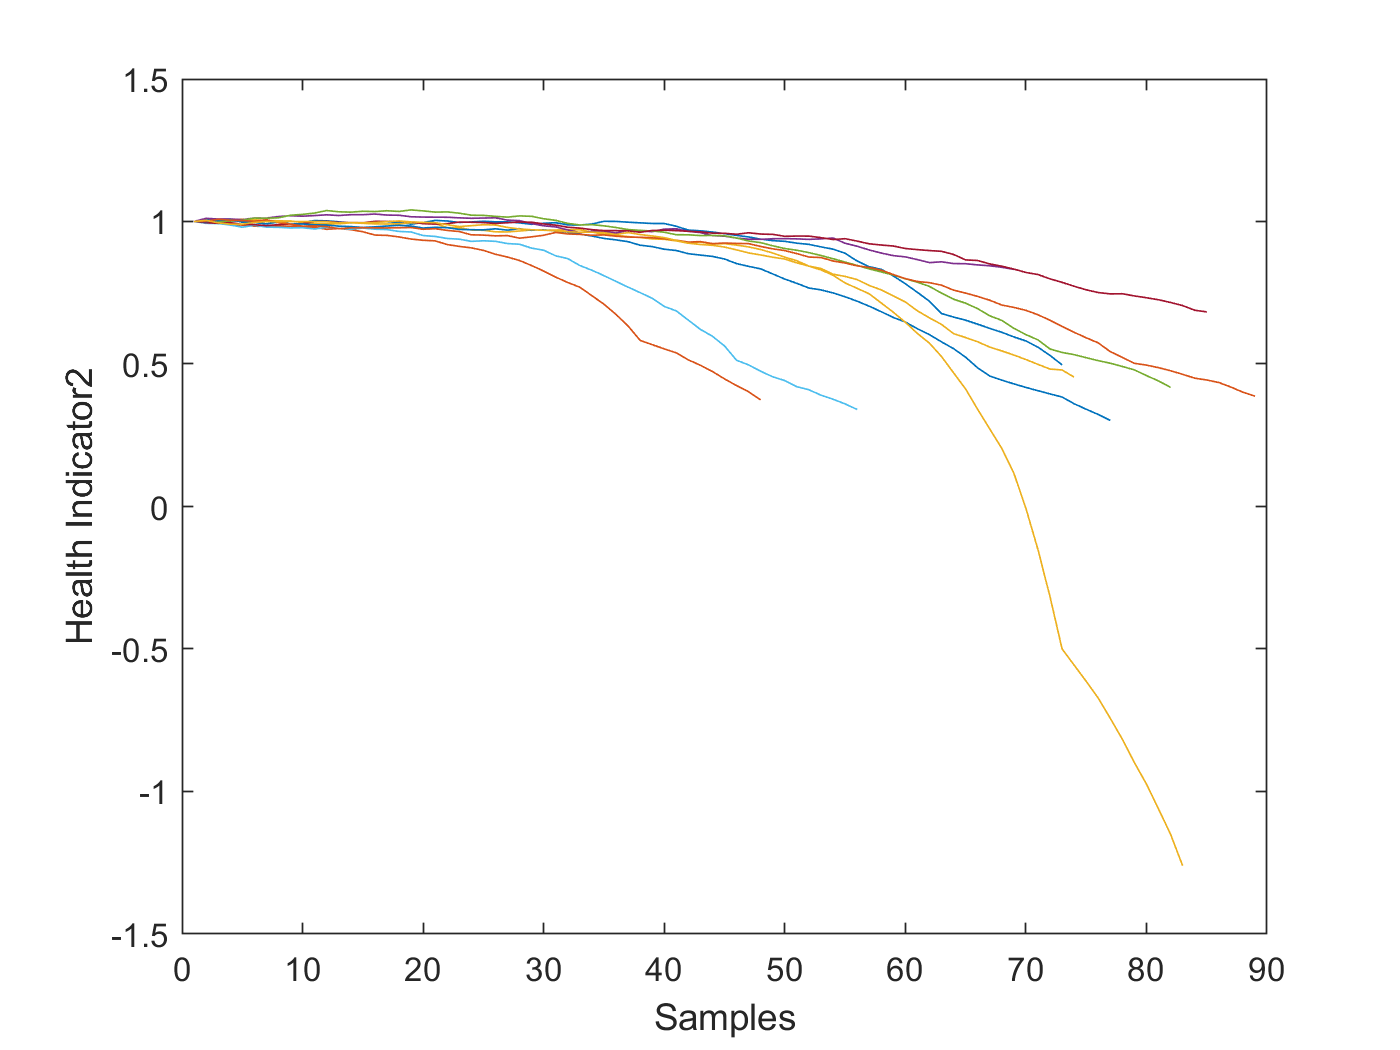

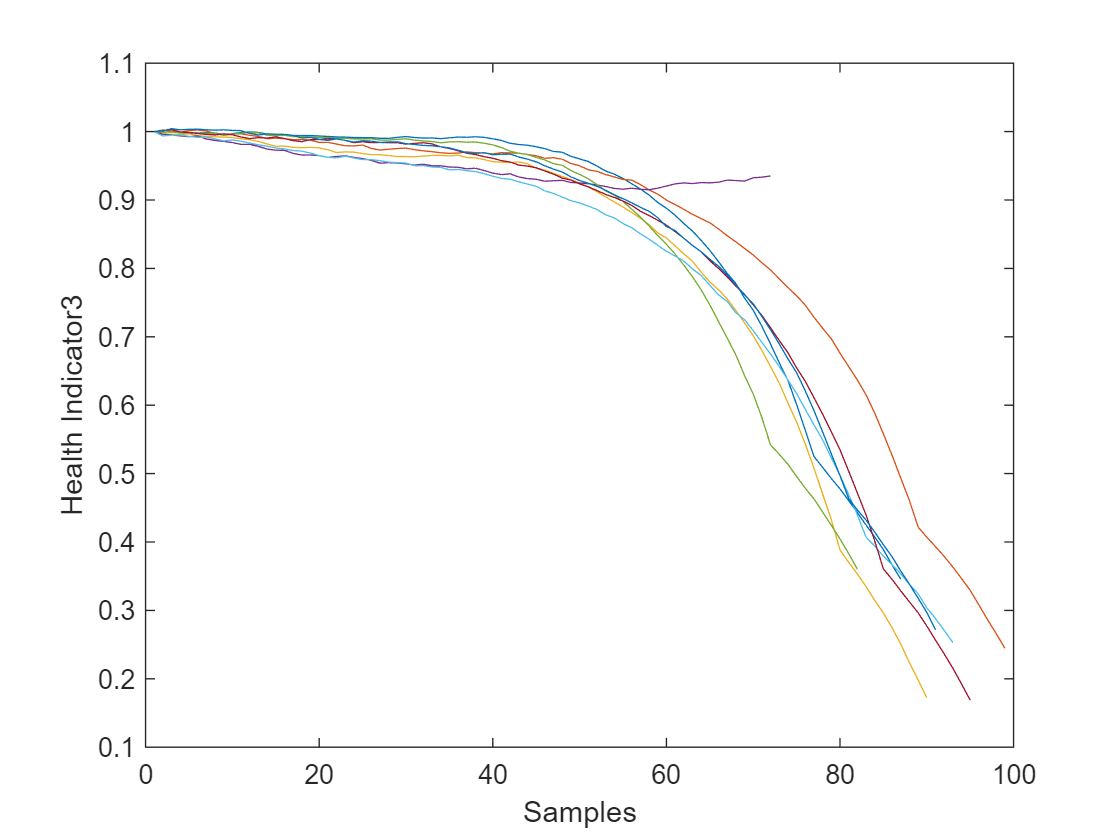

        
        figure
        for k = 1:length(validationDataFused{num_cluster,1})
            plot(validationDataFused{num_cluster,1}{k})
            % title('validationDataFused')
            xlabel('Samples')
            ylabel('Health Indicator'+string(num_cluster))
            % title('ValidationDataFused')
            hold on
        end

end

## Stima della RUL

maxMotore = 10;

mdl = cell(height(trainDataFused),1);
for i = 1:height(mdl)
    mdl{i} = residualSimilarityModel(...
    'Method', 'poly2',...
    'Distance', 'euclidean',...
    'NumNearestNeighbors', Inf,...
    'Standardize', 1);

    fit(mdl{i}, trainDataFused{i,1});
end


## Calcolo RUL 

## Visualizzazione performance e statistiche RUNTIME

In questa sezione vengono mostrati i profili di degradazione con la RUL in RUNTIME.

Siano fissati tre istanti di tempo rispetto alla durata dei Validation Data:

- 50% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

- 70% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

- 90% della durata $\Rightarrow$ calcolo della stima RUL fino a questo momento

% pulizia variabili
clearvars -except mdl trainDataFused validationDataFused maxMotore

%% performance evaluation for test unit 

titolo = "K Nearest Neighbour Point - Unit ";

%mdl_cluster = mdl{2};

%valid = validationDataFused{2,1};

tabella_errori_in_ore = zeros(height(trainDataFused), maxMotore);

for i = 1:3
    valid = validationDataFused{i,1};
    %valid = trainDataFused{i,1};
    mdl_cluster = mdl{i};

    for test_unit = 1:height(valid)
        breakpoint = [0.5, 0.7, 0.9];
        validationDataTmp = valid{test_unit}; 
        %validationDataTmp = valid;


50%

        bpidx = 1;

tabella_errori_in_ore =     0.0147   -0.1520   -0.2103    0.7480    0.0647    0.0003   -0.3353   -0.7036    0.1897    0.7230
   -0.2938   -0.1869   -0.1382   -0.6303   -0.0588   -0.0263   -0.2481    0.2119   -0.0942    0.4175
   -0.0664    0.1029    0.0105   -0.5719   -0.1038    0.0717    0.1628    0.0547         0         0


        validationDataTmp50 = validationDataTmp(1:ceil(end*breakpoint(bpidx)),:);
        trueRUL = length(validationDataTmp) - length(validationDataTmp50);
        [estRUL, ciRUL, pdfRUL] = predictRUL(mdl_cluster, validationDataTmp50);
        
        % figure
        compare(mdl_cluster, validationDataTmp50);
        title(titolo + test_unit + " - 50%")
        xlabel("Number of Samples")

tabella_rmse =     0.4240
    0.2883
    0.2201


        ylabel("Health indicator")
    
        
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 50%")


70%

        bpidx = 2;

s =     0.0281    0.0220    0.0134


        validationDataTmp70 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
        trueRUL = length(validationDataTmp) - length(validationDataTmp70);

score =     0.2260
    0.1552
    0.1168


        [estRUL,ciRUL,pdfRUL] = predictRUL(mdl_cluster, validationDataTmp70);
        
        % figure
        compare(mdl_cluster, validationDataTmp70);  
        title(titolo + test_unit + " - 70%")
        
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 70%")


90%

        bpidx = 3;
        validationDataTmp90 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
        trueRUL = length(validationDataTmp) - length(validationDataTmp90);
        [estRUL,ciRUL,pdfRUL] = predictRUL(mdl_cluster, validationDataTmp90);

        %estRUL = estRUL*90/3600;
        %trueRUL = trueRUL*90/3600;
        %pdfRUL = pdfRUL*90/3600;
        %ciRUL = ciRUL*90/3600;

        % figure
        compare(mdl_cluster, validationDataTmp90);  
        title(titolo + test_unit + " - 90%")
    
        helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)
        title("RUL Estimation Motore " + test_unit + " - 90%")
    

### Calcolo dell'errore sulla RUL

        % calcolo scostamento StimaRUL - trueRUL sull'intera simulazione
    
        numValidation = length(validationDataFused);
        numBreakpoint = length(breakpoint);
        error = zeros(numValidation, numBreakpoint);
    
        tmpData = valid{test_unit};
        % tmpData = valid;
        for bpidx = 1:numBreakpoint
            tmpDataTest = tmpData(1:ceil(end*breakpoint(bpidx)), :);
            trueRUL = length(tmpData) - length(tmpDataTest);
            [estRUL, ~, ~] = predictRUL(mdl_cluster, tmpDataTest);
            error(test_unit, bpidx) = estRUL - trueRUL;
        end


## Visualizzazione delle performance sull'intera simulazione

Stima della pdf (probability density function) nei tre istanti di tempo prima definiti

        [pdf50, x50] = ksdensity(error(:, 1));
        [pdf70, x70] = ksdensity(error(:, 2));
        [pdf90, x90] = ksdensity(error(:, 3));


Confronto tra le pdf ottenute e l'errore

        % figure
        ax(1) = subplot(3,1,1);
        hold on
        %histogram(error(:, 1), 'BinWidth', 1500, 'Normalization', 'pdf')
        line([error(1) error(1)],[0 max(pdf50)],'Color','r','LineWidth',1.5)
        plot(x50, pdf50)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 50% of each validation ensemble member")
        
        ax(2) = subplot(3,1,2);
        hold on
        histogram(error(:, 2), 'BinWidth', 1500, 'Normalization', 'pdf')
        plot(x70, pdf70)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 70% of each validation ensemble member")    
        
        ax(3) = subplot(3,1,3);
        hold on
        histogram(error(:, 3), 'BinWidth', 1500, 'Normalization', 'pdf')
        plot(x90, pdf90)
        hold off
        xlabel('Prediction Error')
        title("Motore " + test_unit + " RUL Prediction Error using first 90% of each validation ensemble member")    
        % linkaxes(ax)


## Visualizzazione delle statistiche dell'errore

Il seguente grafico mostra l'andamento di mediana, 25° percentile, 75° percentile e valori massimi e minimi per ciascuno dei tre istanti di tempo: l'andamento ottimo deve convergere a zero.

        % figure
        boxplot(error, 'Labels', {'50%', '70%', '90%'})
        ylabel('Prediction Error')
        title("Motore " + test_unit + " Prediction error sui 3 istanti di tempo")


Calcolo del valore medio e della dev std

        % calcolo dev std e val med
        errorMean = mean(error);
        errorMedian = median(error);    
        errorSD = std(error);


Il seguente grafico mostra il valore medio $\pm$ dev std per ogni istante dei tre: i valori devono avere un andamento convergente a zero

        % figure
        errorbar([50 70 90], errorMean, errorSD, '-o', 'MarkerEdgeColor','r')
        xlim([40, 100])
        xlabel('Percentage of validation data used for RUL prediction')
        ylabel('Prediction Error')
        %title("Motore " + test_unit + " Valore medio e SD per i 3 istanti di tempo")
        legend('Mean Prediction Error with 1 Standard Deviation Eror bar', 'Location', 'south')
        
        tabella_errori_in_ore(i, test_unit) = (trueRUL - estRUL) * 90/3600;
    end
end

Tabella Errori

tabella_errori_in_ore

Calcolo RMSE

tabella_rmse = zeros(3,1);
for i = 1:3
    n(i) = nnz(tabella_errori_in_ore(i,:));
    tabella_rmse(i) = sqrt((sum(nonzeros(tabella_errori_in_ore(i,:)).^2))/n(i));
end

tabella_rmse
for i = 1:3
    n(i) = nnz(tabella_errori_in_ore(i,:));
    segno = zeros(n(i),1);
    segno = nonzeros(tabella_errori_in_ore(i,:)) > 0;
    segno1 = zeros(n(i),1);
    for k = 1:length(segno)
        if segno(k) > 0
            segno1(k) = 1/13; % sottostimata
        else
            segno1(k) = 1/10;
        end
    end

    s(i) = sum(exp(segno1.*nonzeros(abs(tabella_errori_in_ore(i,:))))-1)/n(i);
end

s

Score della Challenge

score = 0.5*tabella_rmse + 0.5*s'

function [] = helpPlotterPDF(trueRUL, estRUL, pdfRUL, ciRUL)

    p = 125/5000;
    time = 0:p:125-p; % 125 max number of hours
    ora = 90/3600;

    ci1 = ceil(ciRUL(1))*ora;
    ci2 = ceil(ciRUL(2))*ora;
    yMax = max(pdfRUL.ProbabilityDensity);
    xArea = [ci1 ci2 ci2 ci1];
    yArea = [0 0 yMax yMax];

    % figure
    plot(pdfRUL.RUL*ora,pdfRUL.ProbabilityDensity,'b')
    title('RUL Estimation')
    xlabel('Hours')
    ylabel('Probability Density')
    hold on
    line([trueRUL*ora trueRUL*ora],[0 yMax],'Color','r','LineWidth',1.5)
    line([estRUL*ora estRUL*ora],[0 yMax],'Color','g','LineWidth',1.5)
    
    patch(xArea,yArea,'yellow','FaceAlpha',0.3)

    legend('pdfRUL','trueRUL','estRUL','Confidence interval 90%')
    hold off

end

function [] = helperPlotEnsemble(trainDataNormalized, sensorTrended, dataVariables, nsample)

    colonne = sensorTrended(3:6)+1;
    disp(colonne)
    [row,~] = size(trainDataNormalized);
    
    figure
    title('Trend sensori')
    for i = 1:length(colonne)
        subplot(4,1,i)
        for j = 1:row
            hold on
            y = trainDataNormalized{j,1}.(colonne(i))(1:nsample:end);
            plot(y)
            xlabel('Time')
            ylabel(string(dataVariables(colonne(i)-1)))
            title(strcat('Trend sensore ',string(dataVariables(colonne(i)-1))))
        end
        hold off
    end
    hold off
    end
function dataFused = degradationSensorFusion(data, sensorToFuse, weights)
% Combine measurements from different sensors according 
% to the weights, smooth the fused data and offset the data
% so that all the data start from 1

    % Fuse the data according to weights
    dataToFuse = data{:, cellstr(sensorToFuse)};
    dataFusedRaw = dataToFuse*weights;
    
    % Smooth the fused data with moving mean
    stepBackward = 10;
    stepForward = 10;
    dataFused = movmean(dataFusedRaw, [stepBackward stepForward]);
    
    % Offset the data to 1
    dataFused = dataFused + 1 - dataFused(1);
end
